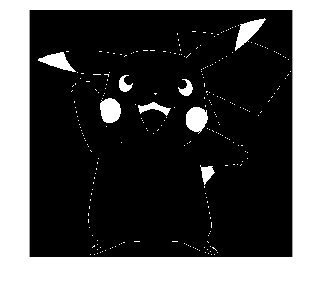

close all; clear all; clc;
IMG = rgb2gray(imread('2.bmp')); % transfer to grayscalce pic
% figure; 
% imshow(IMG);            

% IMG=imrotate(IMG,-90);
IMG = im2bw(IMG,0.5);
IMG=~IMG;
% figure;
% imshow(IMG);
IMG = bwmorph(IMG,'thin');
IMG = bwmorph(IMG,'spur',2);
figure;
imshow(IMG);

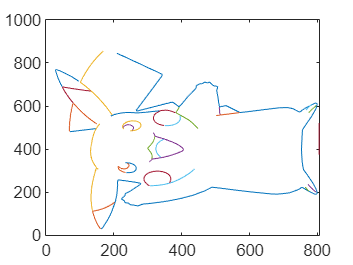


% IMG=bwmorph(IMG,'remove');
% IMG=bwmorph(IMG,'thin');
% IMG=bwmorph(IMG,'clean');
IMG = IMG - imerode(IMG,[0 1 0 ; 1 1 1 ; 0 1 0]);
% figure;
% imshow(IMG);

IMG1=IMG;
IMG0=zeros(size(IMG));
l=100;
pathlength=[0];
path=[0,0];
i=0;

while (l>10)
    i=i+1;
    [C0,C1,IMG1]=contour_get3(IMG1);
    %path=[path;C0(1,:);C0;C0(end,:)];
    path=[path;C0];
    [l,~]=size(C0);
    %sum(sum(C1))
    pathlength(i,1)=l;
%     figure
%     IMG0=C1+IMG0;
%     imshow(IMG0)
    
%    IMG1=linedelete(IMG1,C1);
%     figure
%     imshow(IMG1)
    
%     IMG1=bwmorph(IMG1,'thin');
%     IMG1=bwmorph(IMG1,'clean');
    %IMG1 = bwmorph(IMG1,'spur',5);
%     figure;
%     imshow(IMG1);
end

path=path(2:(end-1),:);
pathlength=pathlength(1:(end-1));

% xx=path(:,1);
% yy=path(:,2);
len=sum(pathlength);
% zz=zeros(len,1);
m=1;
trajectory=zeros(len,4);
keypath=[0,0,0];
keylength=zeros(size(pathlength));
figure
for i=1:size(pathlength)
    xx=smooth(path(m:(m+pathlength(i)-1),1));
    yy=smooth(path(m:(m+pathlength(i)-1),2));
    zz=zeros(size(xx,1),1);
    [T,N,B,k,t0] = frenet(xx,yy,zz);

    temp_xx = [xx; xx];
    temp_xx = temp_xx(2: length(xx)+1) - xx;
    temp_yy = [yy; yy];
    temp_yy = temp_yy(2: length(yy)+1) - yy;
    temp_d = (temp_xx.^2 + temp_yy.^2).^0.5; % distance between two points.
    temp_d(length(xx))=temp_d(length(xx)-1); % temp_s(length(xx))=0 originally
    temp_k = [k; k];
    temp_k = (temp_k(2: length(k)+1) + k)/2;
    temp_r = 1./temp_k; % radius
    temp_s= 2*asin(temp_d/2 ./ temp_r).*temp_r;
    % vel = 1./temp_d(1:length(xx)); % temp_s not good, similar as temp_d...
    % vel = smooth(vel) % try smooth, bad result
    rel_t = [0; temp_s];
    rel_t = rel_t(1: length(xx));  % test temp_s, temp_d
    %===============================

    % ============== output the data ==========================================
    % rel_t = mean(vel)./vel; % relative time
    abs_t = zeros(size(rel_t));
    for j = 1:size(rel_t)
        abs_t(j,1) = sum(rel_t(1:j)); % absolute time, sum of the first n terms
    end
    norm_t = abs_t./abs_t(size(rel_t,1)); % normalize to 1
    % [xx,yy] is the piont in the planar workspace
    % norm_t is the time axis normalized to 1


    trajectory(m:(m+pathlength(i)-1),:)=[xx, yy, norm_t,k];


    m=m+pathlength(i);



    tt =norm_t*20;

    x=0;
    y=0;
    t=0;
    tik = 1; % counter
    n = length(k); % number of points on the path loaded from "Profiler"
    num = 1; % sequence number for the picked points
    % define the first point
    x(num,1) = xx(1);
    y(num,1) = yy(1);
    t(num,1) = tt(1);
    % -------
    num = num + 1;
    for j = 2 : n
        if k(j) > 0.1*max(k)       % case 1: curve is complicated
            tik = tik - 500/n;     % pick more points
        else if k(j) > 0.01*max(k) % case 2: curve is medium complicated
                tik = tik - 100/n; % pick medium points
        else                   % case 3: curve is simple and flat
            tik = tik - 50/n;  % pick fewer points
        end
        end
        if tik <= 0                % pick points when tik <= 0
            x(num,1) = xx(j);
            y(num,1) = yy(j);
            t(num,1) = tt(j);
            num = num + 1;
            tik = 1;               % reset tik
        end
    end
    
    keypath1=[x,y,t];
    keypath=[keypath;keypath1];
    keylength(i)=num-1;
   
    plot(x,y),hold on


end

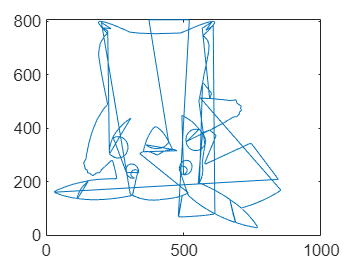


keypath=keypath(2:end,:);
% plot(path(:,1),path(:,2))
figure
plot(keypath(:,2),keypath(:,1))

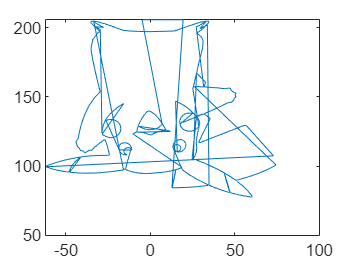




a=22.5;
l=97.5;
h=40;

[m,n]=size(IMG);
syms v
eqn= (v*m+a+2*l*cos(pi*5/12))^2+(v*n/2)^2-(a+2*l)^2==0;
u=solve(eqn,v);
u=max(u);
u=double(u);

%u=0.8*(2*l)^2/sqrt(m^2/4+n^2)^2*(1-cos(pi*5/12))
p2=keypath;%实际尺寸图像，单位mm
p2(:,2)=p2(:,2)-m/2;
p2=p2*u;
p2(:,1)=p2(:,1)+2*l*cos(pi*5/12)+a;
plot(p2(:,2),p2(:,1))

r=1;
qi=zeros(sum(keylength),4);
for j=1:length(keylength)

    p1=p2(r:r+keylength(j)-1,:);
    %     p1(:,2)=p1(:,2)-m/2;
    %     p1=p1*u;
    %     p1(:,1)=p1(:,1)+2*l*cos(pi*5/12);
    for i=1:length(p1)
        x=p1(i,2);
        y=p1(i,1);
        L0=sqrt(x^2+y^2);
%         thetha1=pi/2-mod(atan(y/x),pi);
        thetha1=atan(y/x);
        thetha2=asin(h/L0);
        L1=L0*cos(thetha2)-a;
%         qi(i+r-1,1)=thetha1+thetha2;
        qi(i+r-1,1)=pi/2-mod(thetha1-thetha2,pi);
        qi(i+r-1,2)=abs(acos((L1-a)/l/2));
        qi(i+r-1,3)=2*qi(i+r-1,2);
        qi(i+r-1,4)=-qi(i+r-1,2);
        %q5=-q1;

    end
    r=r+keylength(j);
end

max(qi)

ans =     1.0786    1.4142    2.8284   -0.6198


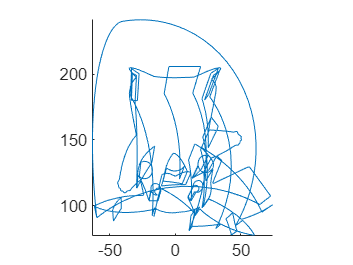


q=jtraj([0 0 0 0],qi(1,:)+[0 pi/6 0 pi/6],50);
q_=jtraj(qi(1,:)+[0 pi/6 0 pi/6],qi(1,:),30);
q=[q;q_;qi(1:keylength(1),:)];
j=1+keylength(1);
for i=2:length(keylength)
    lastpost=qi(j-1,:);
    nextpost=qi(j,:);
    qa=jtraj(lastpost,lastpost+[0 pi/6 0 pi/6],30);
    qb=jtraj(lastpost+[0 pi/6 0 pi/6],nextpost+[0 pi/6 0 pi/6],20);
    qc=jtraj(nextpost+[0 pi/6 0 pi/6],nextpost,30);
    q=[q;qa;qb;qc;qi(j:j+keylength(i)-1,:)];
    j=j+keylength(i);
end
qlast=jtraj(qi(end,:),qi(end,:)+[0 pi/6 0 pi/6],30);
qlast=[qlast;jtraj(qi(end,:)+[0 pi/6 0 pi/6],[0 0 0 0],50)];
q=[q;qlast];

time=length(q);
real=zeros(time,3);
for i=1:time
    q1=q(i,1);
    q2=q(i,2);
    q3=q(i,3);
    real(i,1)=(2*a+l*cos(q2)+l*cos(q3-q2))*sin(q1)-h*cos(q1);
    real(i,2)=(2*a+l*cos(q2)+l*cos(q3-q2))*cos(q1)+h*sin(q1);
    real(i,3)=l*sin(q2)-l*sin(q3-q2);
end

figure
plot3(real(:,1),real(:,2),real(:,3)),axis equal
view ([0 0 1]);


save('pkq.mat','q');
save('pkqmap.mat','p2')